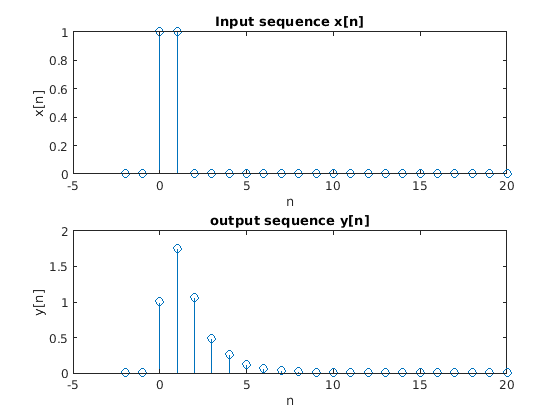

clc;
close all;

b = input('Enter the coefficients of x: ');
a = input('Enter the coefficients of y: ');

M = length(b) - 1;
N = length(a) - 1;
IC = input('Enter the initial conditions for y: ');

n = [-N:20];

x = [(n  >= 0)] - [(n >= 2)];
subplot(211);
stem(n,x);

title('Input sequence x[n]');
xlabel('n');
ylabel('x[n]');

y = [IC zeros(1, length(n)-N)];

for n = N+1:20
    sumx = 0;sumy = 0;

    for k = 0:M
        sumx = sumx + (b(k+1)*x(n-k));
       
    end
    for k = 1:N
        sumy = sumy + (a(k+1)*y(n-k));
    
    end
    y(n) = sumx - sumy;
end

n = [-N:20];

subplot(212);
stem(n,y);

title('output sequence y[n]');
xlabel('n');
ylabel('y[n]');

disp('y[n]=');

y[n]=


disp(y)

         0         0    1.0000    1.7500    1.0625    0.4844    0.2539    0.1240    0.0627    0.0312    0.0156    0.0078    0.0039    0.0020    0.0010    0.0005    0.0002    0.0001    0.0001    0.0000         0         0         0

